# Local Planner Simulation

## function import

addpath("utils/env/", "utils/data/map/", "utils/plot/", "utils/animation/");

addpath("local_planner/");

addpath("global_planner/graph_search/");

addpath("global_planner/sample_search/");

## initialize

clear all;
clc;

% load environment
load("gridmap_20x30_empty.mat");
map_size = size(grid_map);
G = 1;

%moving obs

obs1.v = 2.2; %m/s
obs1.end = [19,24];
obs1.start = [7,3];

% start and goal pose
start = [3, 2, 0];
goal = [18, 25, 0];

% planner
global_planner_name = "a_star";

% local_planner_name = "pid_plan";
local_planner_name = "dwa_plan";
% local_planner_name = "apf_plan";
% local_planner_name = "rpp_plan";
% local_planner_name = "lqr_plan";
% local_planner_name = "mpc_plan";

## Path planning

global_planner = str2func(global_planner_name);
[path, global_flag, cost, expand] = global_planner(grid_map, start(:, 1:2), goal(:, 1:2));

## trajectory planning

local_planner = str2func(local_planner_name);
[pose, traj, local_flag, pose_obs] = local_planner(start, goal, obs1, "path", path, "map", grid_map);

goal arrived!


## visualization

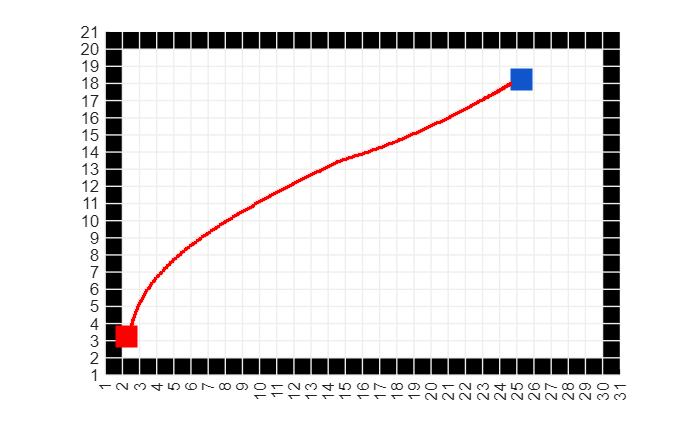

clf;
hold on

% plot grid map
plot_grid(grid_map);
%plot_path(path, G);

% plot start and goal
plot_square(start, map_size, G/2, "#f00");
plot_square(goal, map_size, G/2, "#15c");

% animation
record_video = false;
local_planner_name = "DWA_Test_noObs";
animation(local_planner_name, pose, traj, pose_obs, G , record_video);

hold off